clear all, close all, clc

m = 1;
M = 5;
L = 2;
g = -10;
d = 1;

s = 1; % pendulum up (s=1)

%Linearized System

A = [0 1 0 0;
    0 -d/M -m*g/M 0;
    0 0 0 1;
    0 -s*d/(M*L) -s*(m+M)*g/(M*L) 0];
B = [0; 1/M; 0; s*1/(M*L)];
eig(A)

ans =          0
   -2.4674
   -0.1665
    2.4339



C = eye(4);
sys = ss(A,B,C,0*B);

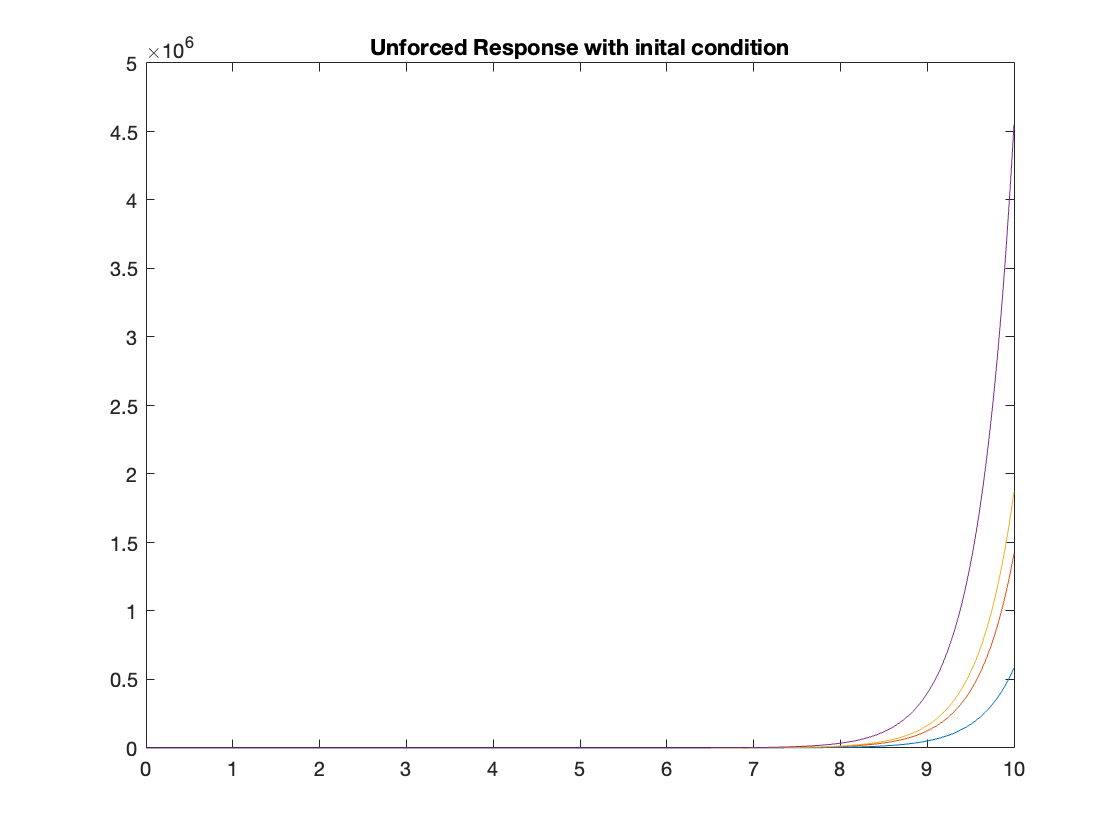

tspan = 0:.001:10;
if(s==-1)
    y0 = [0; 0; 0; 1.5];
    [yL,t,xL] = initial(sys,y0,tspan);
    [t,yNL] = ode45(@(t,y)cartpend(y,m,M,L,g,d,0),tspan,y0);
elseif(s==1)
    y0 = [0; 0; pi+.0001; 0];
    [yL,t,xL] = initial(sys,y0-[0; 0; pi; 0],tspan);
    [t,yNL] = ode45(@(t,y)cartpend(y,m,M,L,g,d,0),tspan,y0);
else    
end

%Unforced Response with inital conditions
figure(1)
plot(t,yL);
title('Unforced Response with inital condition')

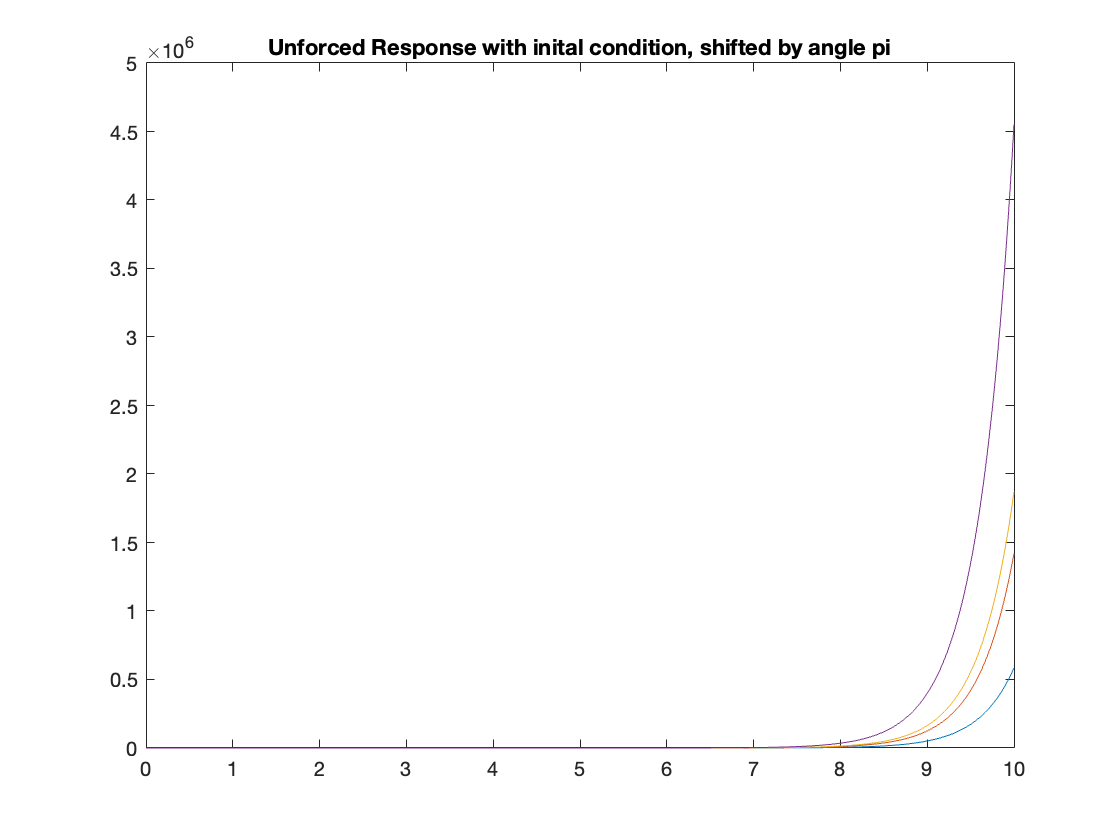

figure(2)
plot(t,yL+ones(10001,1)*[0; 0; pi; 0]');
title('Unforced Response with inital condition, shifted by angle pi')

%plot(t,yNL)


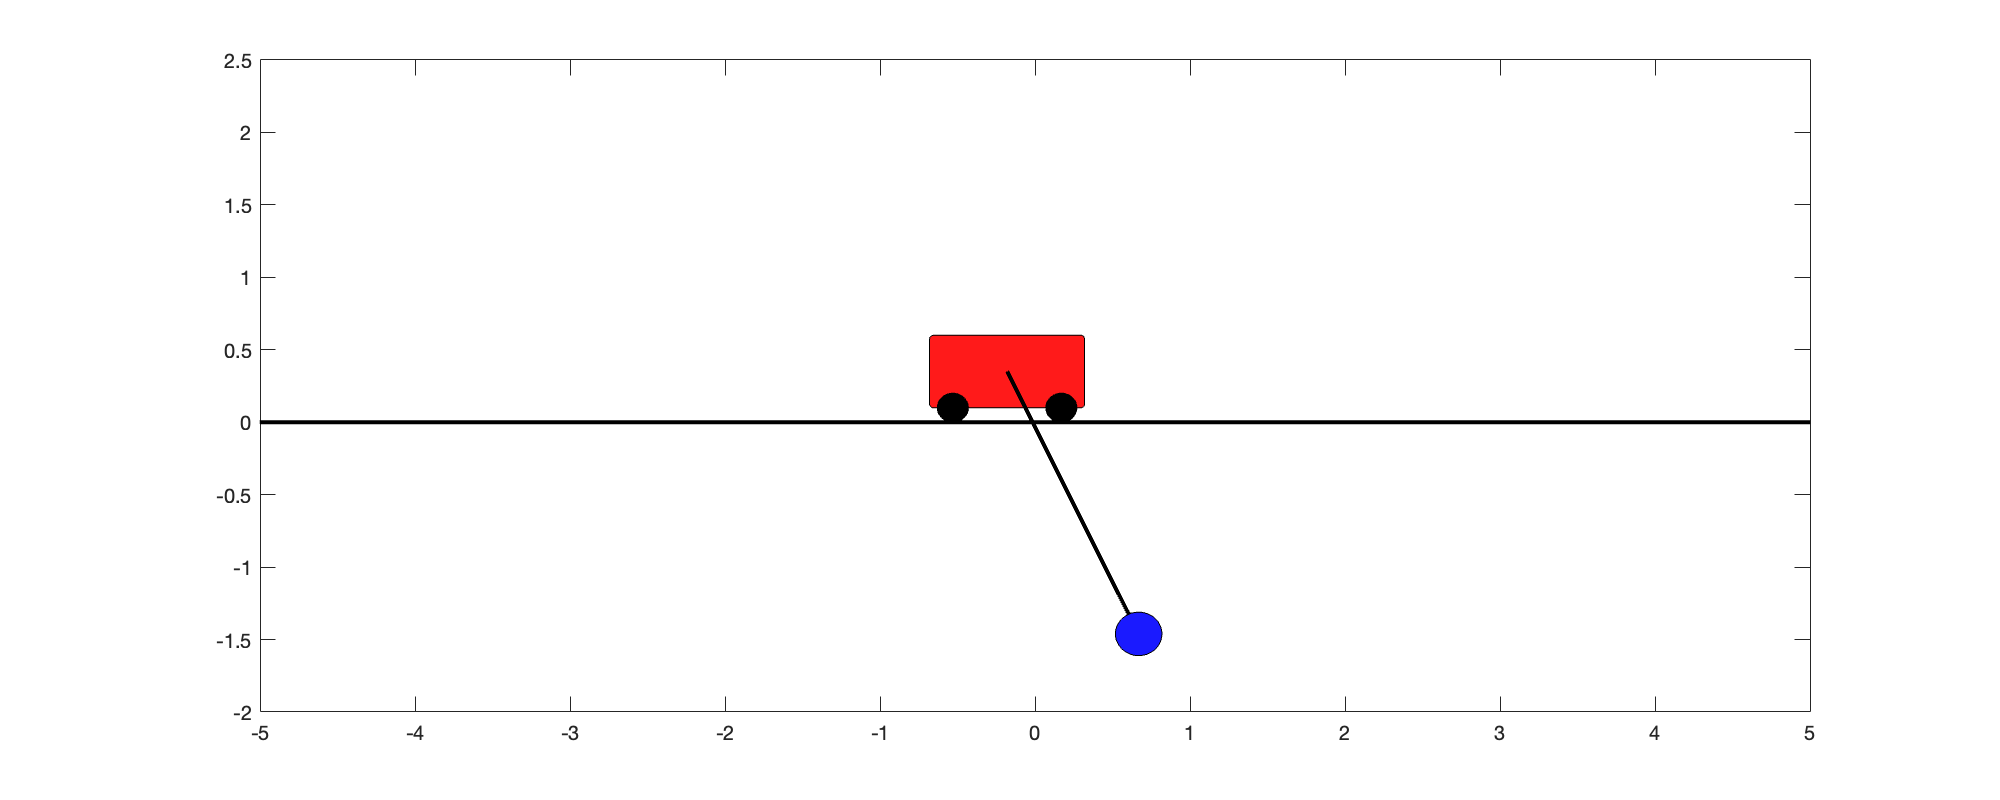


figure(3)
for k=1:100:length(t)
    drawcartpend(yNL(k,:),m,M,L);
end

%Nonlinear Euqaiton for cart on a pendulum

function dy = cartpend(y,m,M,L,g,d,u)
Sy = sin(y(3));
Cy = cos(y(3));
D = m*L*L*(M+m*(1-Cy^2));

dy(1,1) = y(2);
dy(2,1) = (1/D)*(-m^2*L^2*g*Cy*Sy + m*L^2*(m*L*y(4)^2*Sy - d*y(2))) + m*L*L*(1/D)*u;
dy(3,1) = y(4);
dy(4,1) = (1/D)*((m+M)*m*g*L*Sy - m*L*Cy*(m*L*y(4)^2*Sy - d*y(2))) - m*L*Cy*(1/D)*u +.01*randn;
end

function drawcartpend(y,m,M,L)
x = y(1);
th = y(3);

% kinematics
% x = 3;        % cart position
% th = 3*pi/2;   % pendulum angle

% dimensions
% L = 2;  % pendulum length
W = 1*sqrt(M/5);  % cart width
H = .5*sqrt(M/5); % cart height
wr = .2; % wheel radius
mr = .3*sqrt(m); % mass radius

% positions
% y = wr/2; % cart vertical position
y = wr/2+H/2; % cart vertical position
w1x = x-.9*W/2;
w1y = 0;
w2x = x+.9*W/2-wr;
w2y = 0;

px = x + L*sin(th);
py = y - L*cos(th);

plot([-10 10],[0 0],'k','LineWidth',2)
hold on
rectangle('Position',[x-W/2,y-H/2,W,H],'Curvature',.1,'FaceColor',[1 0.1 0.1])
rectangle('Position',[w1x,w1y,wr,wr],'Curvature',1,'FaceColor',[0 0 0])
rectangle('Position',[w2x,w2y,wr,wr],'Curvature',1,'FaceColor',[0 0 0])

plot([x px],[y py],'k','LineWidth',2)

rectangle('Position',[px-mr/2,py-mr/2,mr,mr],'Curvature',1,'FaceColor',[.1 0.1 1])

% set(gca,'YTick',[])
% set(gca,'XTick',[])
xlim([-5 5]);
ylim([-2 2.5]);
set(gcf,'Position',[100 550 1000 400])
% box off
drawnow
hold off
end